## **Heavy Frame**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0 Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea level condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Fuselage Properties**

D = 6.38;                          % Fuselage diameter (m)
r = D ./ 2;                        % Fuselage radius (m)
C = 2 * pi * r;                    % Fuselage circumference (m)

**0.3 Material Properties**

E_f = 67000000000;                 % Young's Modulus (N/m^2)
rho_f = 2860;                      % Density (kg/m^3)
sigma_y = 614000000;               % Tensile yield stress (Pa)
tau_y = sigma_y ./ sqrt(3);        % Shear yield stress (Pa)

pi * sqrt(E_f/sigma_y)

ans = 32.8173

**0.4 Critical Loading Conditions**

Q = -2.080980043509572e+06;       % Maximum shear force (N)
P = 0;                            % Maximum tangential load (N)
T = 0;                            % Maximum torque (Nm)

### **1 WISE curve**

**1.1 Find WISE curve**

% Define theta range (0 to 2*pi for full fuselage section)
theta = linspace(0, 2 * pi, 1000);

% Compute shear flow distributions for P, Q, and T load cases
M_P = -(P * r / (2 * pi)) .* ((3 * sin(theta) / 2) + (pi - theta) .* (cos(theta) - 1));
N_P = -(P / (2 * pi)) .* ((sin(theta) / 2) - (pi - theta) .* cos(theta));
S_P = -(P / (2 * pi)) .* (((pi - theta) .* sin(theta)) - 1 - (cos(theta) / 2));

M_Q = -(Q * r / (2 * pi)) .* ((cos(theta) / 2) - (pi - theta) .* sin(theta) + 1);
N_Q = -(Q / (2 * pi)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_Q = -(Q / (2 * pi)) .* (((pi - theta) .* cos(theta)) - (sin(theta) / 2));

M_T = -(T / (2 * pi)) .* (pi - 2 * sin(theta) - theta);
N_T = -(T / (2 * pi * r)) .* ((3 * cos(theta) / 2) + (pi - theta) .* sin(theta));
S_T = -(T / (2 * pi * r)) .* (1 + 2 * cos(theta));

% Compute total shear flow distributions
M_total = M_P + M_Q + M_T;
N_total = N_P + N_Q + N_T;
S_total = S_P + S_Q + S_T;

1.2 Plotting the result

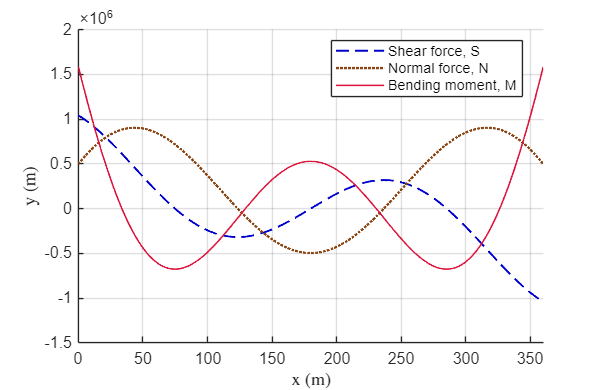

figure(1)

clf;

hold on;

plot(theta * 180 / pi, S_total, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(theta * 180 / pi, N_total, ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 1.5);
plot(theta * 180 / pi, M_total, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.);

% Legends
legend("Shear force, S", "Normal force, N", "Bending moment, M", "Location", "best", 'NumColumns', 1, FontSize = 9)

% Axis labels with LaTeX font
xlabel('x (m)', 'Interpreter', 'latex');
ylabel('y (m)', 'Interpreter', 'latex');

% Set plot limits and grid
xlim([0 360]);
grid on;

hold off;

% Set figure size
set(gcf, 'Position', [0 0 500 325]);

1.3 Find the maximum

S_max = max(abs(S_total))

S_max = 1.0405e+06

N_max = max(abs(N_total))

N_max = 9.0350e+05

M_max = max(abs(M_total))

M_max = 1.5848e+06

### **2 Optimisation Problem using fmincon with Global research**

compare [fmincon](https://www.mathworks.com/help/optim/ug/fmincon.html) with [GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html) and [ga](https://ww2.mathworks.cn/help/gads/ga.html), using the best result

**2.0 Initial conditions**

Define the objective function for optimisation problem

fun = @(x) mass_hf(x(1), x(2), x(3), x(4));            % (t_web, t_fl, b_f, h_f)

Define initial point for the objective function

x0 = [30 / 1000, 30 / 1000, 200 / 1000, 300 / 1000];   % take average from literiture review

Boundary conditions

lb = [1 / 1000, 1 / 1000, 100 / 1000, 100 / 1000]; % change dynamically
ub = [0.05, 0.05, 0.4, 0.5];                           % change dynamically

Nonlinear constraints

nonlcon = @Non_linear_hf_1;

**2.1 Define problem**

Create optimization problem [createOptimProblem](https://ww2.mathworks.cn/help/gads/createoptimproblem.html)

problem = createOptimProblem('fmincon', 'objective', fun, 'x0', x0, 'lb', lb, 'ub', ub, 'nonlcon', nonlcon, 'options', optimoptions('fmincon', 'Display', 'iter'));

[GlobalSearch](https://ww2.mathworks.cn/help/gads/globalsearch.html)

gs = GlobalSearch('NumTrialPoints', 10000, 'MaxWaitCycle', 200);

**2.2 Run optimisation**

[x_opt, f_opt] = fmincon(fun, x0, [], [], [], [], lb, ub, nonlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_opt =     0.0234    0.0323    0.2359    0.2938


f_opt = 1.2663e+03

[x_opt, f_opt] = run(gs, problem);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       5    1.203804e+03    8.848e+07    6.543e+03
    1      10    1.202909e+03    7.407e+07    6.580e+03    7.672e-03
    2      15    1.203219e+03    7.383e+07    6.584e+03    1.265e-04
    3      20    1.203764e+03    7.300e+07    6.582e+03    5.311e-04
    4      25    1.228346e+03    6.596e+07    6.394e+03    1.591e-02
    5      30    1.265494e+03    5.678e+07    6.109e+03    2.017e-02
    6      35    1.265681e+03    5.673e+07    6.108e+03    8.905e-05
    7      40    1.265608e+03    5.668e+07    6.106e+03    2.770e-05
    8      45    1.244472e+03    4.431e+07    5.517e+03    7.641e-03
    9      50    1.244393e+03    4.424e+07    5.520e+03    3.717e-05
   10      55    1.312985e+03    2.818e+06    8.000e+03    2.341e-03
   11      61    1.262596e+03    2.408e+06    7.727e+03    1.054e-02
   12      66    1.262382e+03    2.400e+06    7

   41     216    1.216128e+03    2.560e+03    1.699e+00    1.647e-07


   42     221    1.216125e+03    2.595e+02    1.699e+00    2.377e-07
   43     226    1.216130e+03    2.512e+03    1.699e+00    1.714e-07
   44     231    1.216128e+03    3.223e+02    1.699e+00    2.443e-07
   45     236    1.216133e+03    2.470e+03    1.699e+00    1.661e-07
   46     241    1.216131e+03    3.715e+02    1.699e+00    2.500e-07
   47     246    1.216136e+03    2.432e+03    1.699e+00    1.667e-07
   48     251    1.216133e+03    4.089e+02    1.699e+00    2.532e-07
   49     256    1.216139e+03    2.397e+03    1.699e+00    1.666e-07
   50     261    1.216136e+03    4.366e+02    1.699e+00    2.555e-07
   51     266    1.216142e+03    2.365e+03    1.699e+00    1.661e-07
   52     271    1.216139e+03    4.564e+02    1.698e+00    2.568e-07
   53     276    1.216144e+03    2.336e+03    1.698e+00    1.653e-07
   54     281    1.216142e+03    4.701e+02    1.698e+00    2.572e-07
   55     286    1.216147e+03    2.308e+03    1.698e+00    1.644e-07
   56     291    1.216145e+03    4

   77     396    1.216178e+03    2.049e+03    1.697e+00    1.486e-07


   78     401    1.216176e+03    4.621e+02    1.696e+00    2.350e-07


   79     406    1.216181e+03    2.028e+03    1.696e+00    1.470e-07



Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.

                                            First-order      Norm of
 Iter F-count    

   25     130    1.145903e+03    2.160e+03    3.308e+00    5.776e-07


   26     135    1.145921e+03    1.042e+04    3.307e+00    2.291e-06
   27     140    1.145911e+03    1.695e+03    3.307e+00    2.289e-06


   28     145    1.145927e+03    1.002e+04    3.307e+00    5.247e-07


   29     150    1.145919e+03    1.266e+03    3.307e+00    6.231e-07


   30     155    1.145935e+03    9.697e+03    3.307e+00    5.199e-07



Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.

                                            First-order      Norm of
 Iter F-count    

### **3 Validate Result**

**3.1 Assign x values**

t_web = x_opt(1); % web thickness (m)
t_web * 1000      % 15-25 mm

ans = 21.1903

t_fl = x_opt(2);  % flange thickness (m)
t_fl * 1000       % 25-40 mm

ans = 28.8331


b_f = x_opt(3);   % frame width (m)
b_f * 1000        % 200-400 mm

ans = 214.0817

h_f = x_opt(4);   % frame height (m)
h_f * 1000        % 300-500 mm

ans = 348.0439

**2.2 Calculate mass**

% Find second moment of inertia
[I_x, A] = I_hf(t_web, t_fl, b_f, h_f);
I_x * 1000 ^ 4

ans = 4.4916e+08


A * 1000 ^ 2

ans = 1.9720e+04


% Calcualte frame mass
m_f = rho_f * A * C

m_f = 1.1305e+03

**2.3 Calculate constraint**

% Slenderness ratio
1.2 * sqrt(E_f/sigma_y)

ans = 12.5353

(h_f / t_web) - 1.2 * sqrt(E_f/sigma_y)

ans = 3.8894

h_f / t_web

ans = 16.4247

0.7 * sqrt(E_f/sigma_y)

ans = 7.3123

(b_f / t_fl) - 0.7 * sqrt(E_f/sigma_y)

ans = 0.1126

b_f / t_fl

ans = 7.4248


%
% Maximum direct stress
N_max / A - sigma_y

ans = -5.6818e+08

(sigma_y)  / 1e6

ans = 614

(N_max / A)  / 1e6

ans = 45.8156


%
% Maximum shear stress
Q_x = b_f * t_fl * (h_f/2 - t_fl/2);
(S_max * Q_x) / (I_x * t_web) - tau_y

ans = -2.4679e+08

tau_y  / 1e6

ans = 354.4931

((S_max * Q_x) / (I_x * t_web)) / 1e6

ans = 107.6997


%
% Maximum bending stress
(M_max * h_f) / (2 * I_x) - sigma_y

ans = -0.5479

sigma_y / 1e6

ans = 614

((M_max * h_f) / (2 * I_x)) / 1e6

ans = 614.0000

### **4 Buckling analysis**

% From ESDU datasheet 
% (see Structure 3 Lecture Notes for k to K calculation)
Kc = 3.69; % 3.62 for v = 0.3
Ks = 4.93; % 4.83 for v = 0.3
% Flange Local Buckling:
BCf = Kc * E_f * ((t_fl / b_f) ^ 2);
BCf / 1e6

ans = 4.4846e+03

% Web Shear Buckling:
BCw = Ks * E_f * ((t_web / h_f) ^ 2);
BCw / 1e6

ans = 1.2244e+03

% Web compressive Buckling:
BCw2 = Kc * E_f * ((t_web / h_f) ^ 2);
BCw2 / 1e6

ans = 916.4469